a=1+mod(964,3);

Q1

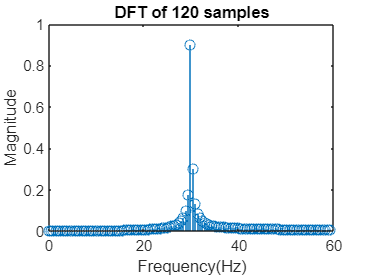

fs=120;
t=0:1/fs:2;
s=sin(2*pi*15*a*t);
y=fft(s);
f=(0:length(y)-1)*fs/length(y);
m=abs(y);
y(m<1e-5)=0;

stem(f(1:120),m(1:120)/120)
title('DFT of 120 samples')
xlabel('Frequency(Hz)')
ylabel('Magnitude')

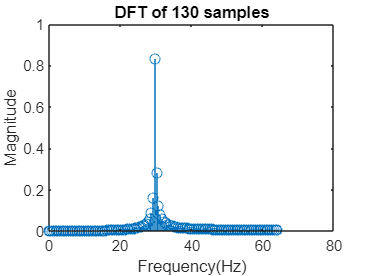

stem(f(1:130),m(1:130)/130)
title('DFT of 130 samples')
xlabel('Frequency(Hz)')
ylabel('Magnitude')

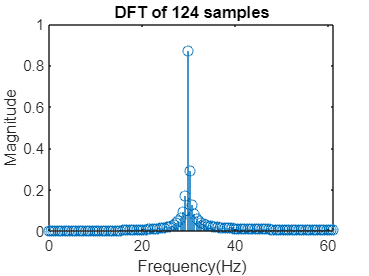



stem(f(1:124),m(1:124)/124)
title('DFT of 124 samples')
xlabel('Frequency(Hz)')
ylabel('Magnitude')

Q2

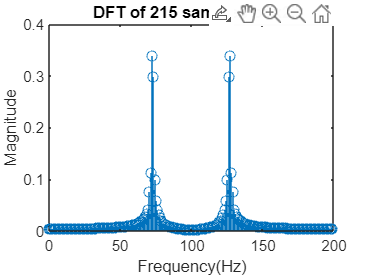

fs=200;
t=0:1/fs:10;
x2= 0.1*sin(140*pi*t) + cos(146*pi*t);
x2=x2(1:215);
y2=fft(x2);
m2=abs(y2);
y2(m2<1e-5)=0;
f2=(0:length(y2)-1)*fs/length(y2);
stem(f2,m2/215)
title('DFT of 215 samples of x2')
xlabel('Frequency(Hz)')
ylabel('Magnitude')

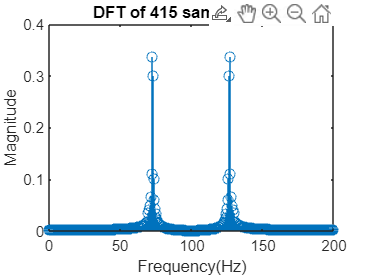



fs=200;
t=0:1/fs:10;
x2= 0.1*sin(140*pi*t) + cos(146*pi*t);
x2=x2(1:415);
y2=fft(x2);
m2=abs(y2);
y2(m2<1e-5)=0;
f2=(0:length(y2)-1)*fs/length(y2);
figure;stem(f2,m2/415)
title('DFT of 415 samples of x2')
xlabel('Frequency(Hz)')
ylabel('Magnitude')

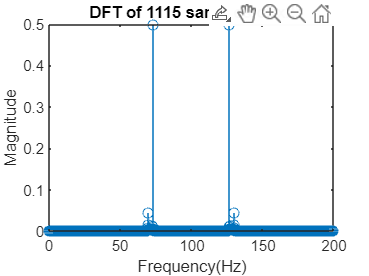


fs=200;
t=0:1/fs:10;
x2= 0.1*sin(140*pi*t) + cos(146*pi*t);
figure;
x2=x2(1:1115);
y2=fft(x2);
m2=abs(y2);
y2(m2<1e-5)=0;
f2=(0:length(y2)-1)*fs/length(y2);
stem(f2,m2/1115)
title('DFT of 1115 samples of x2')
xlabel('Frequency(Hz)')
ylabel('Magnitude')

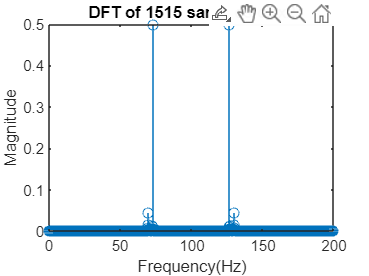



fs=200;
t=0:1/fs:10;
x2= 0.1*sin(140*pi*t) + cos(146*pi*t);
figure;
x2=x2(1:1515);
y2=fft(x2);
m2=abs(y2);
y2(m2<1e-5)=0;
f2=(0:length(y2)-1)*fs/length(y2);
stem(f2,m2/1515)
title('DFT of 1515 samples of x2')
xlabel('Frequency(Hz)')
ylabel('Magnitude')

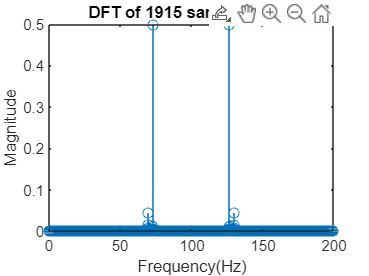



fs=200;
t=0:1/fs:10;
x2= 0.1*sin(140*pi*t) + cos(146*pi*t);
figure;
x2=x2(1:1915);
y2=fft(x2);
m2=abs(y2);
y2(m2<1e-5)=0;
f2=(0:length(y2)-1)*fs/length(y2);
stem(f2,m2/1915)
title('DFT of 1915 samples of x2')
xlabel('Frequency(Hz)')
ylabel('Magnitude')

figure;

Q3

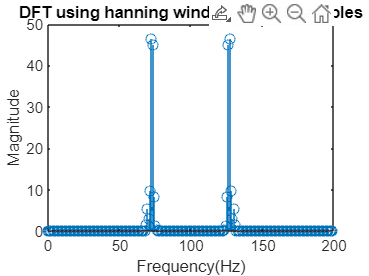

clear
fs=200;
t=0:1/fs:10;
x2= 0.1*sin(140*pi*t) + cos(146*pi*t);
x2=x2(1:215);
l2=215;
%wvtool(hanning(l2));
w2=x2.*hanning(l2)';
w12=fft(w2);
wm2=abs(w12);
w12(wm2<1e-5)=0;
fw2=(0:length(w12)-1)*fs/length(w12);
stem(fw2,wm2)
title('DFT using hanning window for 215 samples')
xlabel('Frequency(Hz)')
ylabel('Magnitude')

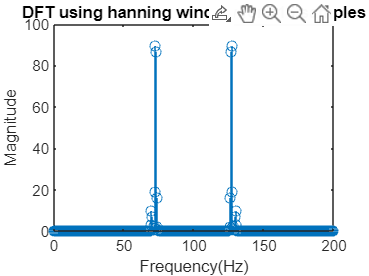

clear
fs=200;
t=0:1/fs:10;
x2= 0.1*sin(140*pi*t) + cos(146*pi*t);
figure;
l2=415;
x2=x2(1:415);
%wvtool(hanning(l2));
w2=x2.*hanning(l2)';
w12=fft(w2);
wm2=abs(w12);
w12(wm2<1e-5)=0;
fw2=(0:length(w12)-1)*fs/length(w12);
stem(fw2,wm2)
title('DFT using hanning window for 415 samples')
xlabel('Frequency(Hz)')
ylabel('Magnitude')


figure;

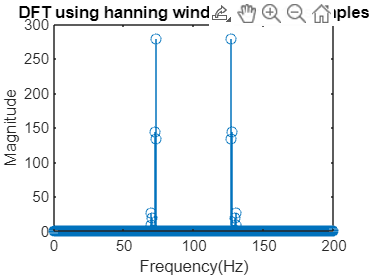

clear
fs=200;
t=0:1/fs:10;
x2= 0.1*sin(140*pi*t) + cos(146*pi*t);

l2=1115;
x2=x2(1:1115);
%wvtool(hanning(l2));
w2=x2.*hanning(l2)';
w12=fft(w2);
wm2=abs(w12);
w12(wm2<1e-5)=0;
fw2=(0:length(w12)-1)*fs/length(w12);
stem(fw2,wm2)
title('DFT using hanning window for 1115 samples')
xlabel('Frequency(Hz)')
ylabel('Magnitude')

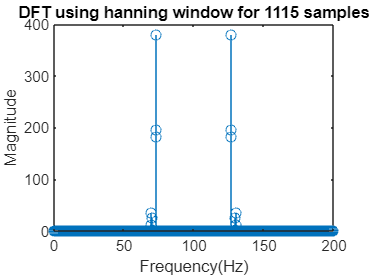

clear
fs=200;
t=0:1/fs:10;

x2= 0.1*sin(140*pi*t) + cos(146*pi*t);

figure;
l2=1515;
x2=x2(1:1515);
%wvtool(hanning(l2));
w2=x2.*hanning(l2)';
w12=fft(w2);
wm2=abs(w12);
w12(wm2<1e-5)=0;
fw2=(0:length(w12)-1)*fs/length(w12);
stem(fw2,wm2)
title('DFT using hanning window for 1115 samples')
xlabel('Frequency(Hz)')
ylabel('Magnitude')

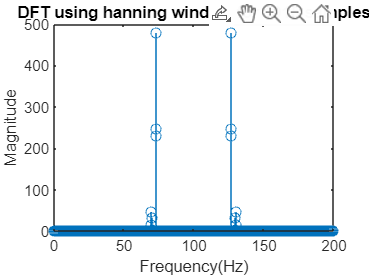

clear
fs=200;
t=0:1/fs:10;

x2= 0.1*sin(140*pi*t) + cos(146*pi*t);
l2=1915;
x2=x2(1:1915);
%wvtool(hanning(l2));
w2=x2.*hanning(l2)';
w12=fft(w2);
wm2=abs(w12);
w12(wm2<1e-5)=0;
fw2=(0:length(w12)-1)*fs/length(w12);
figure;stem(fw2,wm2)
title('DFT using hanning window for 1915 samples')
xlabel('Frequency(Hz)')
ylabel('Magnitude')



figure;

Q4

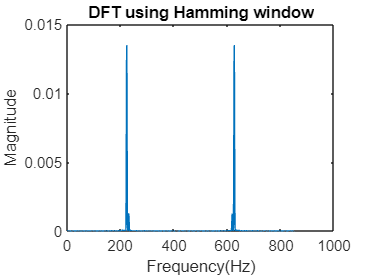

data=load("Exp4Data2.txt");
N=length(data);
fs=850;
Nfft=10000;

ham=hamming(500);
wham=data.*(ham)';
fft_ham=fft(wham,Nfft);
f_ham=(0:length(fft_ham)-1)*fs/length(fft_ham);

rectangluar=rectwin(500);
wrect=data.*rectangluar';
fft_rect=fft(wrect,Nfft);
f_rect=(0:length(fft_rect)-1)*fs/length(fft_rect);
a1=abs(fft_ham);
a2=abs(fft_rect);
figure;
plot(f_ham,a1/length(a1))
title('DFT using Hamming window')
xlabel('Frequency(Hz)')
ylabel('Magnitude')

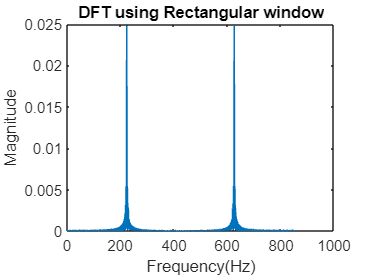

plot(f_rect,a2/length(a2))
title('DFT using Rectangular window')
xlabel('Frequency(Hz)')
ylabel('Magnitude')


[maxvalh,idxh]=max(fft_ham);
[maxvalr,idxr]=max(fft_rect);
fmaxh=f_ham(idxh)/fs

fmaxh = 0.7368

fmaxr=f_rect(idxr)

fmaxr = 626.2800